direction_names = ["FF","BF","FB","BB"];

s = sysf_two_link_lowRe;
nlinks = length(s.geometry.linklengths);

s = ensure_connection_and_metric(s); % required for create_grids
s = create_grids(s)

s = struct with fields:
      geometry: [1×1 struct]
          noop: 1
         n_dim: 1
        visual: [1×1 struct]
       physics: [1×1 struct]
             A: @(alpha1)LowRE_local_connection(s.geometry,s.physics,[alpha1])
        metric: @(alpha1)LowRE_dissipation_metric(s.geometry,s.physics,[alpha1])
    grid_range: [-3.1000 3.1000]
       density: [1×1 struct]
      tic_locs: [1×1 struct]
         A_num: @(alpha1)LowRE_local_connection(s.geometry,s.physics,[alpha1])
          grid: [1×1 struct]


a_grid = s.grid.eval{1};
adot_grid = s.grid.eval{1}*0.1;

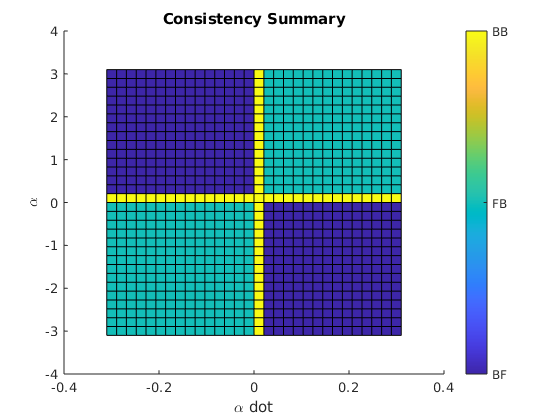

% find which system is consistent when
[system_map, count] = identify_piecewise_system(s, adot_grid);

% look at symmetry and missing/redundant areas
figure(5);
clf(5);
title("Consistency Summary");
xlabel("\alpha dot");
ylabel("\alpha");
surface(adot_grid, a_grid, system_map);
colorbar('Ticks',[1, 2, 3, 4],...
         'TickLabels',direction_names)

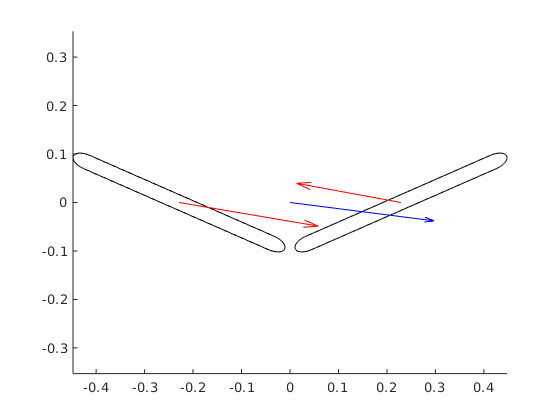

% get a body velocity
i = 20; j = 30;
bvel = apply_piecewise_system(s, system_map, 2, 0.1);

% get link velocities
lvel = zeros(nlinks, 3); % 3 is x y theta

% get Jfull(alpha)
[~, ~, J_full, ~, ~] = N_link_chain(s.geometry, a_grid(i));

for link = 1:nlinks
    lvel(link, :) = J_full{link} * [bvel; adot_grid(j)];
end

% plot
velocity_diagram(s, lvel, bvel, a_grid(i), adot_grid(j), 0, 0);

% define gait functions
% entry 1: anonymous function for a(t)
% entry 2: anonymous function for adot(t) (derivative of a(t))
centered_gait = {@(t) 1 * sin(t), @(t) 1 * cos(t)};
offset_gait = {@(t) 1 + 1 * sin(t), @(t) 1 * cos(t)};
offset_gait2 = {@(t) -1 + 1 * sin(t), @(t) 1 * cos(t)};
tiny_gait = {@(t) 0.5 * sin(t), @(t) 0.5 * cos(t)};
huge_gait = {@(t) 3 * sin(t), @(t) 3 * cos(t)};
gait = huge_gait;

% apply ODE solver
% [t_solution, g_solution] = asym_solve_gait(s, tiny_gait, system_map);
% tiny_gait_displacement = g_solution(size(g_solution,1),:)
% 
% [t_solution, g_solution] = asym_solve_gait(s, offset_gait, system_map);
% offset_gait_displacement = g_solution(size(g_solution,1),:)
% 
% [t_solution, g_solution] = asym_solve_gait(s, offset_gait2, system_map);
% offset_gait2_displacement = g_solution(size(g_solution,1),:)
% 
% [t_solution, g_solution] = asym_solve_gait(s, centered_gait, system_map);
% centered_gait_displacement = g_solution(size(g_solution,1),:)
sol = asym_solve_gait(s, gait, system_map);
gait_displacement = deval(sol, 2*pi)

gait_displacement =     0.2060
    0.0355
   -0.0001


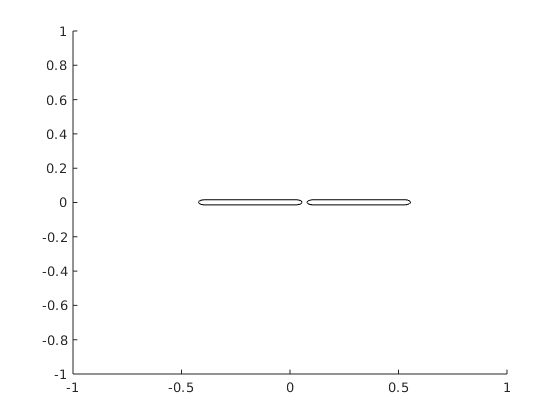

F = animate_asymmetric_solution(s, sol, gait);

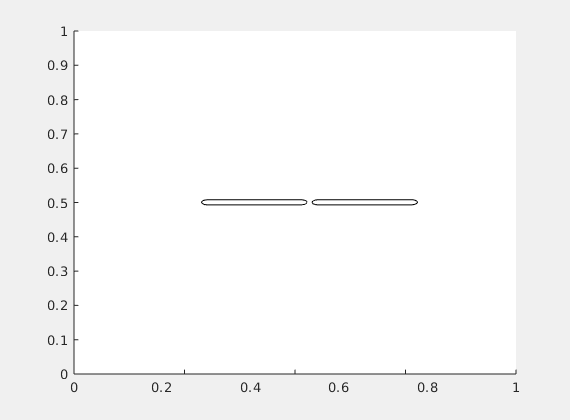

% play movie
figure('visible','on') %forces animation visible in live script
movie(F);

% write movie
v = VideoWriter('AsymmetricFriction/animation_test_1link.avi');
open(v);
writeVideo(v, F);
close(v);

% It's animating something!
% Things to do:
% - have body origin path traced out during animation
% - add motion blur
% - test with no-scales snake (physics check)

% attempting to plot A as a function of alpha:

% connection_grid = [a_grid index, xyt, opening/closing]
connection_grid = zeros([length(a_grid),3,2]);
for i=1:length(a_grid)
    connection_grid(i,:,1) = -get_correct_A(s, a_grid(i), true);
    connection_grid(i,:,2) = -get_correct_A(s, a_grid(i), false);
end

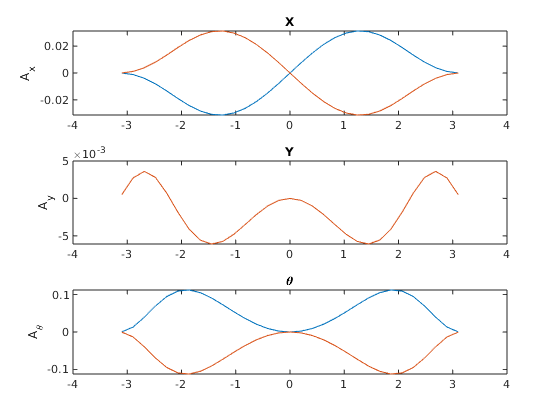

% try some plotting
figure()
tiledlayout(3,1)

% X plot
ax1 = nexttile;
plot(ax1,a_grid, connection_grid(:,1,1), a_grid, connection_grid(:,1,2))
title(ax1,'X')
ylabel(ax1,'A_x')

% Y plot
ax2 = nexttile;
plot(ax2,a_grid, connection_grid(:,2,1), a_grid, connection_grid(:,2,2))
title(ax2,'Y')
ylabel(ax2,'A_y')

% Theta plot
ax2 = nexttile;
plot(ax2,a_grid, connection_grid(:,3,1), a_grid, connection_grid(:,3,2))
title(ax2,'\theta')
ylabel(ax2,'A_\theta')

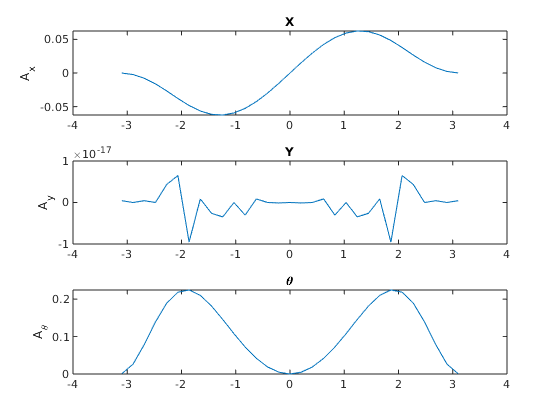

% plot the differences
figure()
tiledlayout(3,1)

% X plot
ax1 = nexttile;
plot(ax1,a_grid, connection_grid(:,1,1) - connection_grid(:,1,2))
title(ax1,'X')
ylabel(ax1,'A_x')

% Y plot
ax2 = nexttile;
plot(ax2,a_grid, connection_grid(:,2,1) - connection_grid(:,2,2))
title(ax2,'Y')
ylabel(ax2,'A_y')

% Theta plot
ax2 = nexttile;
plot(ax2,a_grid, connection_grid(:,3,1) - connection_grid(:,3,2))
title(ax2,'\theta')
ylabel(ax2,'A_\theta')

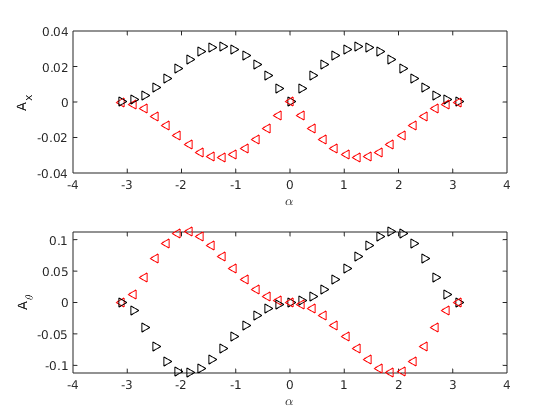

% directional glyphs
figure()
tiledlayout(2,1)
half_grid = floor(length(a_grid)/2);
negative = 1:half_grid;
positive = half_grid+1:length(a_grid);

% X plot
ax1 = nexttile;
plot(ax1,a_grid(negative), connection_grid(negative,1,1), 'r<', ...
    a_grid(negative), connection_grid(negative,1,2), 'k>', ...
    a_grid(positive), connection_grid(positive,1,1), 'k>', ...
    a_grid(positive), connection_grid(positive,1,2), 'r<')
ylabel(ax1,'A_x')
xlabel(ax1,'\alpha')

% Theta plot
ax2 = nexttile;
plot(ax2,a_grid(negative), connection_grid(negative,3,1), 'r<', ...
    a_grid(negative), connection_grid(negative,3,2), 'k>', ...
    a_grid(positive), connection_grid(positive,3,1), 'k>', ...
    a_grid(positive), connection_grid(positive,3,2), 'r<')
ylabel(ax2,'A_\theta')
xlabel(ax2, '\alpha')

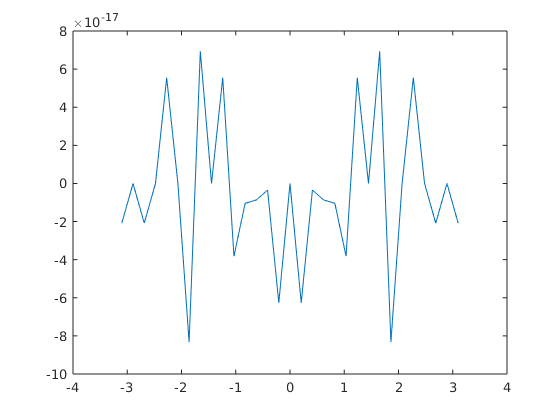

% average Atheta = 0?
figure()
plot(a_grid, (connection_grid(:,3,1) + connection_grid(:,3,2))/2)

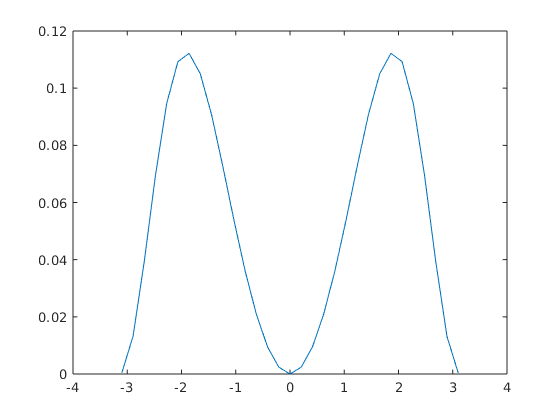


% for half the path, it's going backwards?
figure()
plot(a_grid, (connection_grid(:,3,1) - connection_grid(:,3,2))/2)

% x = (1, 2, NAN, 2, 3)
% y = (0, 1, NAN, 0, 1)
% slope plots

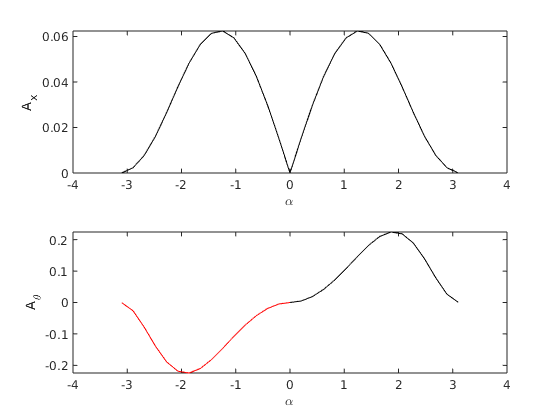

% directional glyphs
figure()
tiledlayout(2,1)
half_grid = floor(length(a_grid)/2);
negative = 1:half_grid+1;
positive = half_grid+1:length(a_grid);

% X plot
ax1 = nexttile;
plot(ax1,a_grid(negative), connection_grid(negative,1,2)-connection_grid(negative,1,1),'k', ...
    a_grid(positive), connection_grid(positive,1,1) - connection_grid(positive,1,2),'k')
ylabel(ax1,'A_x')
xlabel(ax1, '\alpha')

% Theta plot
ax2 = nexttile;
plot(ax2,a_grid(negative), connection_grid(negative,3,2) - connection_grid(negative,3,1),'r', ...
    a_grid(positive), connection_grid(positive,3,1) - connection_grid(positive,3,2),'k')
ylabel(ax2,'A_\theta')
xlabel(ax2, '\alpha')

% do these without the asymmetry, too